# AuE-ME 4600-6600: Dynamic Performance of Vehicles

# Fall 2022 Midterm Exam – Take Home Portion

## Chinmay Vilas Samak

## Solution 1:

clear; close all; clc;
m = 1450; % mass (kg)
Pw = 220*745.6998; % engine power at wheels (W)
rho = 1.225; % air density (kg/m^3)
u = 0.91; % friction coefficient

### 1A.

Af = 1.6+(0.00056*(m-765)); % Approximation for Af based on vehicle mass

Traction limited acceleration: $Fa \cdot v = (\mu \cdot m \cdot g \cdot v) - Fd \cdot v$


$$\Rightarrow m \cdot a = \mu \cdot m \cdot g - 0.5 \cdot \rho \cdot v^2 \cdot Cd \cdot Af$$



$$\Rightarrow Cd = \frac{\mu \cdot m \cdot g - m \cdot a}{0.5 \cdot \rho \cdot v^2 \cdot Af}$$


v1 = 30/3.6; % velocity reading 1 (m/s)
a1 = 0.905*9.81; % acceleration reading 1 (m/s^2)
v2 = 50/3.6; % velocity reading 2 (m/s)
a2 = 0.895*9.81; % acceleration reading 2 (m/s^2)
Cd1 = ((u*m*9.81)-(m*a1))/(0.5*rho*v1^2*Af); % drag coefficient corresponding to v1, a1
Cd2 = ((u*m*9.81)-(m*a2))/(0.5*rho*v2^2*Af); % drag coefficient corresponding to v2, a2
Cd = (Cd1+Cd2)/2; % mean Cd from Cd1 and Cd2

At terminal velocity (power limited acceleration), $a = 0 \Rightarrow Fa = m \cdot a = 0$ $\Rightarrow 0 = Pw - v \cdot Fd$ $\Rightarrow v = Pw/Fd $ $\Rightarrow v^3 = Pw / (0.5 \cdot \rho \cdot Cd \cdot Af)$ $\Rightarrow v = \sqrt[3]{Pw / (0.5 \cdot \rho \cdot Cd \cdot Af)}$

v = nthroot(Pw/(0.5*rho*Cd*Af),3); % terminal velocity (m/s)
fprintf("Terminal velocity, v = %f m/s", v);

Terminal velocity, v = 53.603682 m/s

### 1B.

Fd = 0.5*rho*v^2*Cd*Af; % aerodynamic drag force (N)
d = Fd/m; % decelertation due to aerodynamic drag (m/s^2)
fprintf("Deceleration due to aerodynamic drag, d = %f m/s^2", d);

Deceleration due to aerodynamic drag, d = 2.110688 m/s^2

### 1C.

ay = 0.5*9.81; % lateral acceleration (m/s^2)
Fy = m*ay; % lateral force (N)
alpha = 5*(pi/180); % slip angle (rad)
Fyd = Fy*sin(alpha); % induced drag force (N)
fprintf("Induced drag force, Fyd = %f N", Fyd);

Induced drag force, Fyd = 619.873431 N

### 1D.

Power equation accounting inducted drag:


$$Fa \cdot v = Pw - v \cdot Fd - v \cdot Fyd$$


At terminal velocity, $a = 0 \Rightarrow Fa \cdot v = m \cdot a \cdot v = 0$ $\Rightarrow 0 = Pw - v \cdot Fd - v \cdot Fyd$

we know that aerodynamic drag force, $Fd = 0.5 \cdot \rho \cdot v^2 \cdot Cd \cdot Af $

also, we know that induced drag force, $Fyd = Fy \cdot \sin\alpha = m \cdot ay \cdot \sin\alpha = m \cdot \left ( \frac{v^2}{R} \right ) \cdot \sin\alpha$


$$\Rightarrow Pw - v^3 \left ( 0.5 \cdot \rho \cdot Cd \cdot Af \right ) - v^3 \left ( \frac{m \cdot \sin\alpha}{R} \right ) = 0$$



$$\Rightarrow Pw - v^3 \left ( 0.5 \cdot \rho \cdot Cd \cdot Af + \frac{m \cdot \sin\alpha}{R} \right ) = 0$$



$$\Rightarrow v^3 = \frac{Pw}{\left ( 0.5 \cdot \rho \cdot Cd \cdot Af + \frac{m \cdot \sin\alpha}{R} \right )}$$



$$\Rightarrow v = \sqrt[3]{\frac{Pw}{\left ( 0.5 \cdot \rho \cdot Cd \cdot Af + \frac{m \cdot \sin\alpha}{R} \right )}}$$


## Problem 2:

clear; close all; clc;
m = 1500; % mass (kg)
Cd = 0.5; % drag coefficient
Af = 2.2; % frontal area (m^2)
v_top = 240/3.6; % top speed (m/s)
a = 0.16/2; % half tire print length (m)
CY = 6.25*1e6; % lateral stiffness per unit length (N/m^2)
u_max = 1.3; % maximum friction coefficient
MZ = 160; % self-aligning moment (Nm)

### 2A.

FY = MZ*(3/a); % lateral force (N)
SA = FY/(2*CY*a^2); % slip angle (rad)
fprintf("Total lateral force produced by the tires, FY = %f N\n" + ...
        "Slip angle at which the tires were running, SA = %f rad", FY, SA);

Total lateral force produced by the tires, FY = 6000.000000 N
Slip angle at which the tires were running, SA = 0.075000 rad

### 2B.

rho = 1.225; % air density (kg/m^3)
Fd = 0.5*rho*v_top^2*Cd*Af; % aerodynamic drag force (N)
Pw = Fd*v_top; % engine power at wheels (W)
Fyd = FY*sin(SA); % induced drag force (N)
v = Pw/(Fd+Fyd); % velocity of the vehicle (m/s) -- P=F*v ==> v=P/F
fprintf("Speed of the vehicle, v = %f m/s", v);

Speed of the vehicle, v = 57.964087 m/s

### 2C.

ay = FY/m; % lateral acceleration (m/s^2)
R = v^2/ay; % radius of circle (m)
fprintf("Lateral acceleration, ay = %f m/s^2\n" + ...
        "Radius of circle, R = %f m", ay, R);

Lateral acceleration, ay = 4.000000 m/s^2
Radius of circle, R = 839.958836 m

### 2D.


$${\textrm{Fy}}_{\textrm{parabolic}} =\mu \cdot \textrm{Fz}\cdot \left\lbrack 3\cdot \theta \cdot \sigma_y -3\cdot \theta^2 \cdot \sigma_y^2 +\theta^3 \cdot \sigma_y^3 \right\rbrack$$


w.k.t. ${\textrm{Fy}}_{\textrm{parabolic}} ={\textrm{Fy}}_{\textrm{linear}}$ (from part 2A)


$$\Rightarrow \frac{{\textrm{Fy}}_{\textrm{linear}} }{\mu \cdot \textrm{Fz}}=\left\lbrack 3\cdot \theta \cdot \sigma_y -3\cdot \theta^2 \cdot \sigma_y^2 +\theta^3 \cdot \sigma_y^3 \right\rbrack$$



$$\Rightarrow \theta^3 \cdot \sigma_y^3 -3\cdot \theta^2 \cdot \sigma_y^2 +3\cdot \theta \cdot \sigma_y -\frac{{\textrm{Fy}}_{\textrm{linear}} }{\mu \cdot \textrm{Fz}}=0$$


w.k.t. $\theta$ and $\frac{{\textrm{Fy}}_{\textrm{linear}} }{\mu \cdot \textrm{Fz}}$ are constants (known values), so we can solve above equation for $\sigma_y$ by finding its roots.

FZ = (m*9.81)/4; % normal load on each tire (N)
T = (2*a^2*CY)/(3*u_max*FZ); % theta (intermediate variable)
coeff = [T^3 -3*T^2 3*T -(FY/4)/(u_max*FZ)]; % coefficients of polynomial derived above
SY = roots(coeff); % roots of polynomial
% find real root(s) of polynomial
for i=1:length(SY)
    if isreal(SY(i))
        SY_real = SY(i);
    end
end
SA_parabolic = atan(SY_real); % slip angle (rad)
fprintf("Slip angle (considering lateral force determined in part A, employing brush tire model with parabolic pressure distribution), SA = %f rad", SA_parabolic);

Slip angle (considering lateral force determined in part A, employing brush tire model with parabolic pressure distribution), SA = 0.021142 rad

### 2E.

FZ = (m*9.81)/4; % normal load on each tire (N)
FY_parabolic = u_max*FZ; % maximum lateral load each tire can take (N)
ay = FY_parabolic/m; % maximum lateral acceleration each tire can take (m/s^2)
v = sqrt(R*ay); % maximum velocity before total sliding would occur (m/s)
fprintf("Maximum velocity before total sliding occurs (considering radius determined in part C, employing brush tire model with parabolic pressure distribution), v = %f m/s", v);

Maximum velocity before total sliding occurs (considering radius determined in part C, employing brush tire model with parabolic pressure distribution), v = 51.749384 m/s

### 2F.

a = 0.55; % distance of COG from front (%)
b = 0.45; % distance of COG from rear (%)
CYf = (FY/4)/SA; % cornering stiffness of front tire (N/rad)
CYr = (a/b)*CYf; % cornering stiffness of rear tire (N/rad)
fprintf("Rear cornering stiffness (to make the vehicle neutral-steer under given conditions), CYr = %f N/rad", CYr);

Rear cornering stiffness (to make the vehicle neutral-steer under given conditions), CYr = 24444.444444 N/rad

## Problem 3:

clear; close all; clc;

### 3A.

FZ = -1200*4.4482; % normal load (N)
SA = 4*pi/180; % slip angle (rad)
u = 2+(0.0004*FZ); % friction coefficient
C = (0.0003*FZ^2)+(0.8*FZ); % cornering stiffness (N/rad)
a_bar = (C*tan(SA))/(u*FZ); % non-dimensional slip angle
F_bar = sin(1.4*atan(0.7*a_bar)); % non-dimensional lateral force (B=0.7, C=1.4, D=1, E=0)
FY = F_bar*u*FZ; % lateral force (N)
fprintf("Lateral force corresponding to 4 deg slip angle and -1200 lb normal load, FY = %f N", FY);

Lateral force corresponding to 4 deg slip angle and -1200 lb normal load, FY = 277.909578 N

### 3B.

FZ = 4500; % normal load (N)
a = 0.04; % half patch length (m)
K = 0.15; % slip ratio
u = 0.8; % friction coefficient
CX = 1300*10000; % longitudinal stiffness of the tire (N/m^2)
T = (2*a^2*CX)/(3*u*FZ); % theta (intermediate variable)
SX = K/(1+K); % theoretical slip from slip ratio
FX = u*FZ*((3*T*SX)-(3*T^2*SX^2)+(T^3*SX^3)); % longitudinal force (N) based on brush model assuming parabolic pressure distribution
fprintf("Longitudinal force corresponding to 0.15 slip ratio, FX = %f N", FX);

Longitudinal force corresponding to 0.15 slip ratio, FX = 3156.490284 N

### 3C.

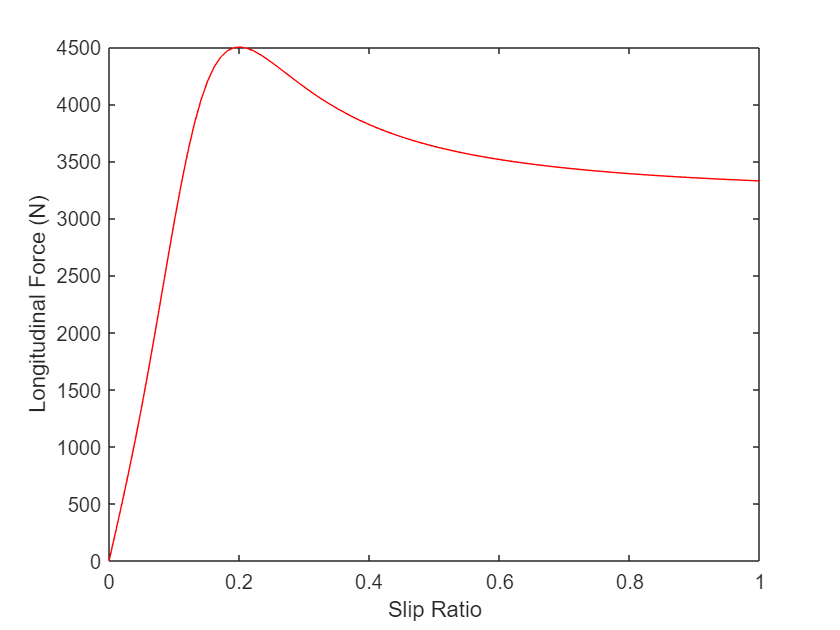

FZ = 4500; % normal load (N)
up = 1.0; % road adhesion (friction coefficient at peak value)
us = 0.7; % friction coefficient at asymptotic value
s1 = 0.04; % slip ratio reading 1
FX1 = 1000; % longitudinal force reading 1
s2 = 0.2; % slip ratio reading 2
FX2 = up*FZ; % peak longitudinal force (reading 2)
s0 = 0; FX0 = 0; % assuming the longitudinal force is 0 at 0 slip ratio
D = FX2; % peak FX
xm = s2; % slip ratio corresponding to peak FX
BCD = (FX1-FX0)/(s1-s0); % slope in linear range (0<=s<=0.04), m = (y2-y1)/(x2-x1)
ys = us*FZ; % asymptotic longitudinal force
C = 1+(1-((2/pi)*asin(ys/D)));
B = BCD/(C*D);
E = ((B*xm)-tan(pi/(2*C)))/((B*xm)-atan(B*xm));
% analysis of relationship between longitudinal force and slip ratio
X = linspace(0,1); % input (slip ratio)
Y = D*sin(C*atan((B*X)-E*((B*X)-atan((B*X))))); % output (longitudinal force corresponding to slip ratio)
figure()
plot(X,Y,'-','color','red')
xlabel("Slip Ratio")
ylabel("Longitudinal Force (N)")

## Solution 4:

clear; close all; clc;
FZ = [-3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -3.325 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -5.55 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775 -7.775].*1000; % normal load (N)
SA = [-3 -2 -1 0 1 2 3 4 5 6 7 8 -3 -2 -1 0 1 2 3 4 5 6 7 8 -3 -2 -1 0 1 2 3 4 5 6 7 8].*(pi/180); % slip angle (rad)
IA = [4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4 4].*(pi/180); % inclination angle (rad)
P  = [221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221 221].*1000; % inflation pressure (Pa)
FY = [5.159 4.4 2.899 0.16 -2.522 -4.348 -5.439 -5.824 -6.008 -5.935 -5.851 -5.779 8.042 6.943 4.533 0.391 -3.751 -6.941 -8.611 -9.315 -9.374 -9.287 -9.052 -8.902 10.536 9.191 6.271 1.427 -3.967 -8.256 -11.004 -12.163 -12.477 -12.386 -12.187 -11.971].*1000; % lateral force (N)
RL = [27.67 27.71 27.76 27.8 27.77 27.71 27.66 27.63 27.62 27.63 27.63 27.63 27.35 27.43 27.57 27.66 27.6 27.43 27.3 27.24 27.23 27.24 27.26 27.28 26.99 27.12 27.34 27.52 27.45 27.19 26.93 26.8 26.76 26.77 26.8 26.82].*0.01; % loaded radius (m)

### 4A.

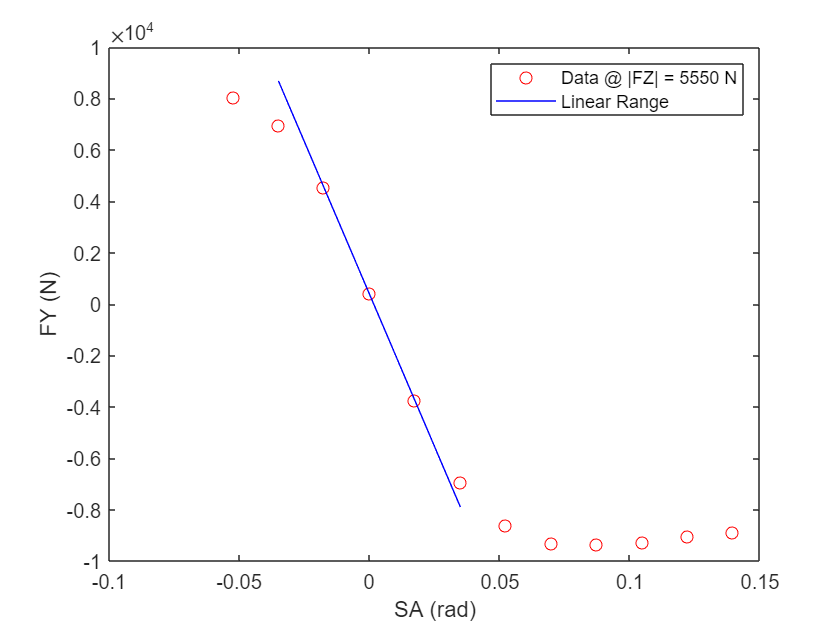

idx = find(FZ==-5550); % filter data (get array indices corresponding to FZ = -5550 N)
SA5550 = SA(idx); % slip angle (rad) corresponding to FZ = -5550 N
FY5550 = FY(idx); % lateral force (N) corresponding to FZ = -5550 N
FZRLpoly = polyfit(SA5550(3:5),FY5550(3:5),1); % fit polynomial (line) to FY vs SA data in linear range
figure()
plot(SA5550,FY5550, 'o','color','red')
hold on
plot(SA5550(2:6),polyval(FZRLpoly,SA5550(2:6)),'-','color','blue')
xlabel("SA (rad)")
ylabel("FY (N)")
legend("Data @ |FZ| = 5550 N","Linear Range",'Location','NE')
%xlim([0, 0.15])
%ylim([-10000, 0]) 
%set(gca, 'YDir','reverse')
hold off

dFYdSApoly = polyder(FZRLpoly); % compute derivative (slope) of polynomial fit to FY vs SA data
C = polyval(dFYdSApoly, 0); % cornering stiffness [value of slope/derivative (dFYdSpoly) at SA = 0 rad]
fprintf("Cornering stiffness (at -5550 N normal load), C = %f N/rad", C);

Cornering stiffness (at -5550 N normal load), C = -237319.118743 N/rad

### 4B.

% positive SA (left turn) corresponds to negative FY, hence, peak FY will be minimum value
u = min(FY5550)/(-5550); % friction coefficient [absolute value of peak FY divided by normal load]
fprintf("Friction coefficient (at -5550 N normal load), u = %f", u);

Friction coefficient (at -5550 N normal load), u = 1.689009

### 4C.

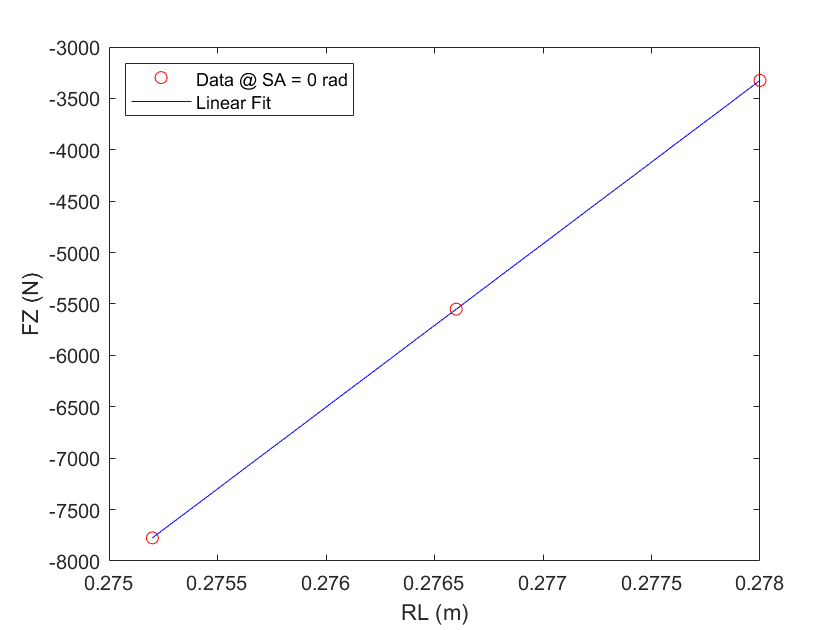

% disregarding the condition to solve only for FZ = -5550 N because we need multiple FZ values to calculate vertical spring rate
idx = find(SA==0); % filter data (get array indices corresponding to SA = 0 rad)
FZ0 = FZ(idx); % normal load (N) corresponding to SA = 0 rad
RL0 = RL(idx); % loaded radius (m) corresponding to SA = 0 rad
FZRLpoly = polyfit(RL0,FZ0,1); % fit polynomial (line) to FZ vs RL data at SA = 0 rad
figure()
plot(RL0,FZ0, 'o','color','red')
hold on
plot(RL0,polyval(FZRLpoly,RL0),'-','color','blue')
xlabel("RL (m)")
ylabel("FZ (N)")
legend("Data @ SA = 0 rad","Linear Fit",'Location','NW')
hold off

k = polyder(FZRLpoly);
fprintf("Vertical spring rate (at 0 rad slip angle), k = %f N/m", k)

Vertical spring rate (at 0 rad slip angle), k = 1589285.714286 N/m

### 4D.

idx = find(FZ==-5550 & SA==deg2rad(3)); % filter data (get array indices corresponding to FZ = -5550 N and SA = 3 deg)
FY3 = FY(idx); % lateral force (N) corresponding to SA = 3 deg
FYd = FY3*sind(3); % induced drag (N) at 3 deg slip angle
fprintf("Induced drag (at -5550 N normal load and 3 deg slip angle), FYd = %f N", FYd)

Induced drag (at -5550 N normal load and 3 deg slip angle), FYd = -450.664919 N

## Problem 5:

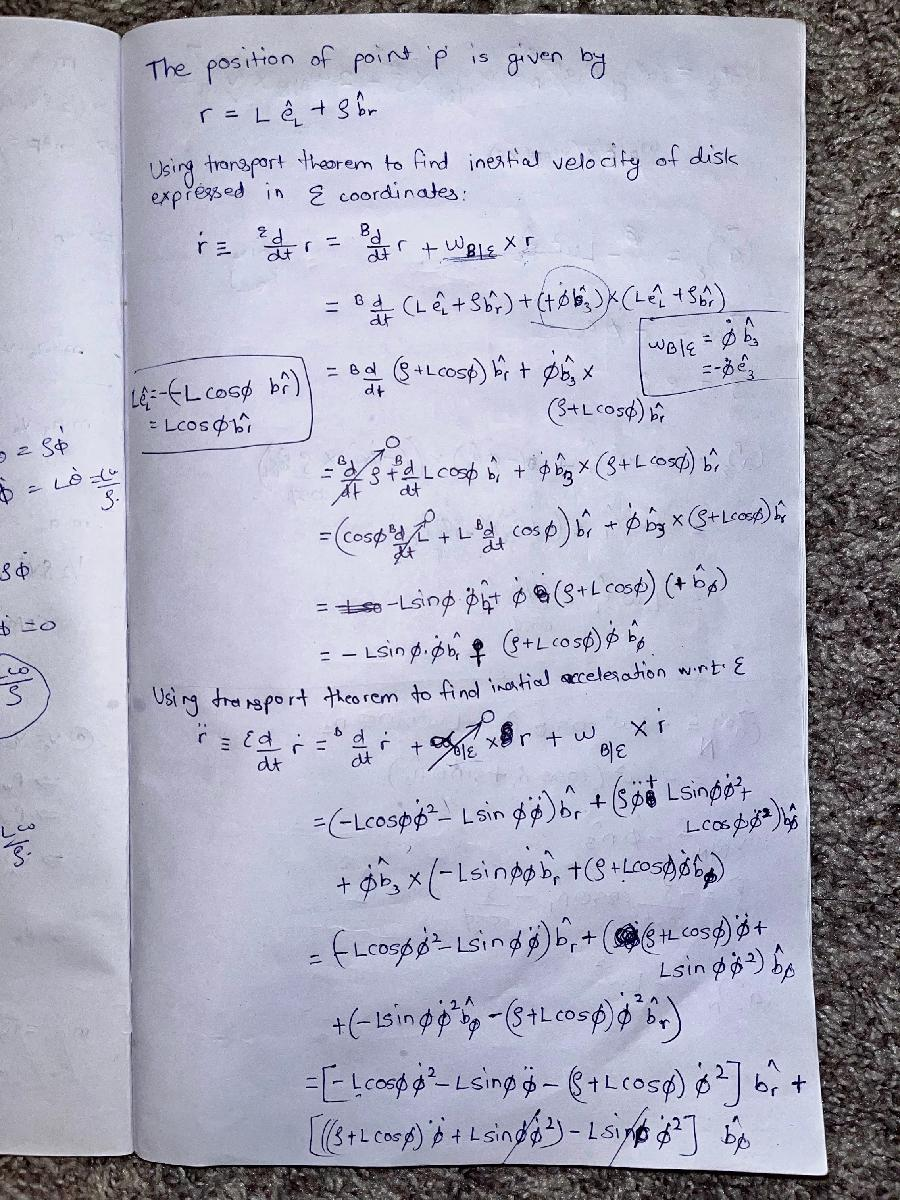

## Solution 6:

clear; close all; clc;
R1 = 230; % large corner radius (m)
R2 = 180; % small corner radius (m)
L = 0.45*1609.344; % length of straight (m)

### 6C.

ay1 = 1.1*9.81; % lateral acceleration in large corner (m/s^2)
ay2 = 1.2*9.81; % lateral acceleration in small corner (m/s^2)
vc1 = abs(sqrt(R1*ay1)); % velocity in large corner (m/s)
vc2 = abs(sqrt(R2*ay2)); % velocity in small corner (m/s)
fprintf("Velocity in corner 1 (ZW), vc1 = %f m/s\n" + ...
        "Velocity in corner 2 (XY), vc2 = %f m/s", vc1, vc2);

Velocity in corner 1 (ZW), vc1 = 49.818972 m/s
Velocity in corner 2 (XY), vc2 = 46.032163 m/s

### 6E.

% location of transition point (St) lies at the intersection of forward and braking velocity curves
af = 0.5*9.81; % forward acceleration (m/s^2)
ab = 1.3*9.81; % braking acceleration (m/s^2)
St1 = (vc2^2-vc1^2+(2*ab*L))/(2*(af+ab)); % transition point along straight 1 (WX) (m) | vf=vc1, vb=vc2
St2 = (vc1^2-vc2^2+(2*ab*L))/(2*(af+ab)); % transition point along straight 2 (YZ) (m) | vf=vc2, vb=vc1
fprintf("Location of transition point along straight 1 (WX), St1 = %f m\n" + ...
        "Location of transition point along straight 2 (YZ), St2 = %f m", St1, St2);

Location of transition point along straight 1 (WX), St1 = 512.759022 m
Location of transition point along straight 2 (YZ), St2 = 533.314578 m

### 6D.

% maximum speed on straight is at location of transition point (St)
vm1 = abs(sqrt(vc1^2+(2*af*St1))); % maximum velocity along straight 1 (WX) (m/s)
vm2 = abs(sqrt(vc2^2+(2*af*St2))); % maximum velocity along straight 2 (YZ) (m/s)
fprintf("Maximum velocity along straight 1 (WX), vm1 = %f m/s\n" + ...
        "Maximum velocity along straight 2 (YZ), vm2 = %f m/s", vm1, vm2);

Maximum velocity along straight 1 (WX), vm1 = 86.672349 m/s
Maximum velocity along straight 2 (YZ), vm2 = 85.736667 m/s

### 6B.

% calculate average speed along the 6 zones of the track (W-St1-X-Y-St2-Z-W) to compute net average speed for 1 lap
s1 = St1; % distance along W-->St1
v1 = (vc1+vm1)/2; % average speed along W-->St1
s2 = L-St1; % distance along St1-->X
v2 = (vm1+vc2)/2; % average speed along St1-->X
s3 = pi*R2; % distance along X-->Y
v3 = vc2; % average speed along X-->Y
s4 = St2; % distance along Y-->St2
v4 = (vc2+vm2)/2; % average speed along Y-->St2
s5 = L-St2; % distance along St2-->Z
v5 = (vm2+vc1)/2; % average speed along St2-->Z
s6 = pi*R1; % distance along Z-->W
v6 = vc1; % average speed along Z-->W
va = (s1+s2+s3+s4+s5+s6)/((s1/v1)+(s2/v2)+(s3/v3)+(s4/v4)+(s5/v5)+(s6/v6)); % average speed for 1 lap (total distance / total time)
fprintf("Average speed for 1 lap, va = %f m/s", va);

Average speed for 1 lap, va = 56.538839 m/s

### 6A.

% minimum time required for 1 lap can be computed based on the total distance in 1 lap and the average speed for 1 lap
% note: we already solved the racing problem for maximum possible average speed
tm = (s1+s2+s3+s4+s5+s6)/va; % minimum time required for 1 lap
fprintf("Minimum time required for 1 lap, tm = %f s", tm);

Minimum time required for 1 lap, tm = 48.399695 s